Constants

syms a b real
assumeAlso(a > 0 & b > 0)

State variables

syms x y real
s = [x;y];

State equations

dx = a + x^2*y - b*x - x;
dy = -x^2*y + b*x;
f = [dx;dy];

sol = solve(f)

sol = struct with fields:
    x: a
    y: b/a


Eq = [sol.x ; sol.y]

$$Eq = \left(\begin{array}{c} a\\ \frac{b}{a} \end{array}\right)$$

The fixed point becomes unstable when $b > 1 + a^2$.

Numerical values

a = 1;
b = 3;
f_ode = matlabFunction(subs(f),'Vars',{sym('t'),s});

s0 = [a;b/a]*1.001;
[tt,xx] = ode89(f_ode,[0 40],s0);

f1_fh = matlabFunction(subs(f(1)));
f2_fh = matlabFunction(subs(f(2)));

[xMesh, yMesh] = meshgrid(linspace(0,5,301));

ff1 = f1_fh(xMesh,yMesh);
ff2 = f2_fh(xMesh,yMesh);

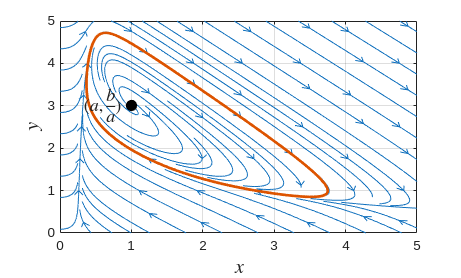

fig = figure(31);
Tl = tiledlayout(1,1);
hold on, box on, grid on;

streamslice(xMesh,yMesh,ff1,ff2);

ldx = tt > 30;
plot(xx(ldx,1),xx(ldx,2),'LineWidth',2)
Eq_ = double(subs(Eq));
plot(Eq_(1),Eq_(2),'k.','MarkerSize',25)
text(Eq_(1),Eq_(2),'$(a,\frac{b}{a})~~$','Interpreter','latex','FontSize',13,'HorizontalAlignment','right')
xlabel('$x$','Interpreter','latex','FontSize',15);
ylabel('$y$','Interpreter','latex','FontSize',15);

$$f = \left(\begin{array}{c} a-x-b\,x+x^{2}\,y\\ b\,x-x^{2}\,y \end{array}\right)$$

exportgraphics(fig,'/home/ppolcz/Dropbox/Peti/PhD/Oktatas/11_NDS/2025/Tematika/fig/Brusselator_LC.pdf','ContentType','vector');